# Fordamper

clc; clear;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");

C:\Users\mkeri\anaconda3\lib\site-packages\numpy\__init__.py:143: UserWarning: mkl-service package failed to import, therefore Intel(R) MKL initialization ensuring its correct out-of-the box operation under condition when Gnu OpenMP had already been loaded by Python process is not assured. Please install mkl-service package, see http://github.com/IntelPython/mkl-service
  from . import _distributor_init


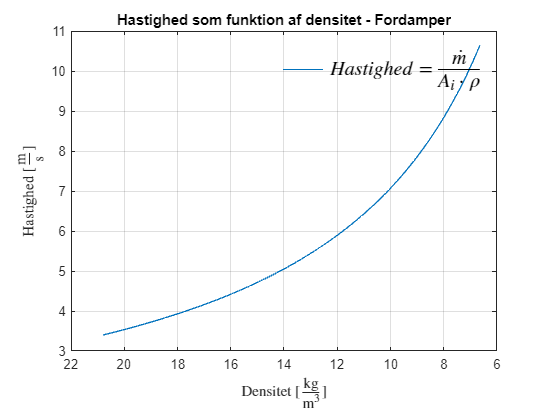

middel = "R134a";
h1 = 3.904*1e5;
h4 = 2.423*1e5; % I J/kg
p4 = 1.327*1e5; % I pascal

hlin = linspace(h4,h1,100);
plin = linspace(p4,p4,100);

qmr = 0.00338*u.kg/u.s;

A_i = 4.78*1e-5;

% Fordamper densitet og hastigheder

Ds = zeros(1, length(hlin));

for i = 1:length(hlin)
    Ds(i) = CP.PropsSI("D","H",hlin(i),"P",plin(i), middel);
end

vs_fordamp = zeros(1,length(hlin));

for h = 1:length(hlin)
    vs_fordamp(h) = separateUnits(qmr)/(Ds(h)*A_i);
end

figure
plot(Ds, vs_fordamp)

grid("on")
title("Hastighed som funktion af densitet - Fordamper")
xlabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")
ylabel("Hastighed [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")

legend("$Hastighed = \frac{\dot{m}}{A_i \cdot\rho}$","Interpreter","latex","FontSize",15,"Box","off")

set(gca, "XDir","reverse")

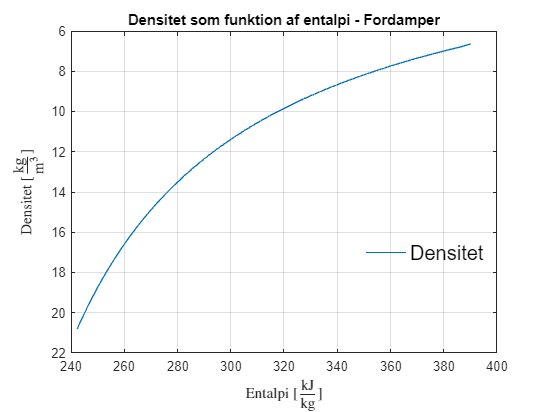


figure
plot(hlin/1e3, Ds)

grid("on")
title("Densitet som funktion af entalpi - Fordamper")
xlabel("Entalpi [$\frac{\mathrm{kJ}}{\mathrm{kg}}$]","Interpreter","latex")
ylabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")

legend("Densitet","location","best","FontSize",15,"box","off")

set(gca, "YDir","reverse")


% 
% Ts = zeros(1,length(hlin));
% 
% for j = 1:length(hlin)
%     Ts(i) = CP.PropsSI("T","D",Ds(j), "P",plin(j), middel);
%     
% end




## Energi i løbet af fordamper

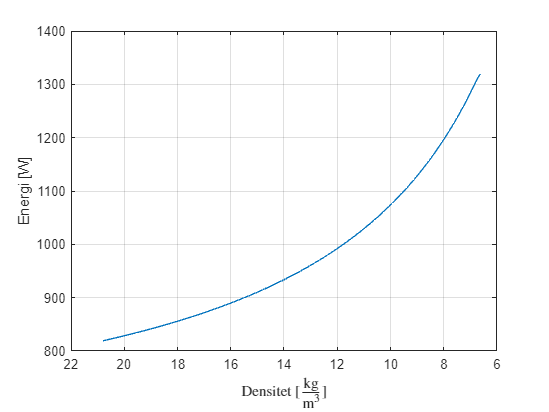

hs_units = hlin.*u.J/u.kg;

W_fordamp = vpa(qmr.*hs_units,6);

Wfordamp_plot = separateUnits(W_fordamp);

figure
plot(Ds, Wfordamp_plot)

grid("on")
ylabel("Energi [W]")
xlabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")
set(gca, "XDir","reverse")



kond_ror = 7*u.m; % meter
vs_units = vpa(mean(vs_fordamp)*u.m/u.s,4)

$$vs\_units = 7.006\,\frac{m}{s}$$


t_i_ror = vpa(kond_ror/vs_units,4)

$$t\_i\_ror = 0.9991\,s$$



fordamp_Wdiff = max(Wfordamp_plot) - min(Wfordamp_plot);



fordamp_W_eff = fordamp_Wdiff*(u.J/u.s);%*t_i_ror;
fordamp_W_eff = vpa(unitConvert(fordamp_W_eff,"SI","Derived"),4)

$$fordamp\_W\_eff = 500.6\,W$$



% 500 watt i sekundet
% Hvor meget energi er der i saltvandsblandingen? Det er nødvendigt at
% vide, for at finde ud af hvor lang tid det vil tage at køle ned 
% Modstande skal inkluderes


# Beregninger til brine

CPvand = vpa(CP.PropsSI("C","T",294,"Q",0,"Water"),3)*u.J/(u.kg*u.K)

$$CPvand = 4183.78652274608612060546875\,\frac{J}{K\,\mathrm{kg}}$$

CPsalt = 0.853 * u.J/(u.g*u.K);
CPsalt = unitConvert(CPsalt,u.J/(u.kg*u.K))

$$CPsalt = 853\,\frac{J}{K\,\mathrm{kg}}$$



CPbrine = 0.75*CPvand + 0.25*CPsalt;
dT = 30*u.K;
mbrine = 20*u.kg;

Ebrine = mbrine*dT*CPbrine;

unitConvert(Ebrine/fordamp_W_eff,u.h)

$$ans = 1.1157401683852148038750003563501\,h$$